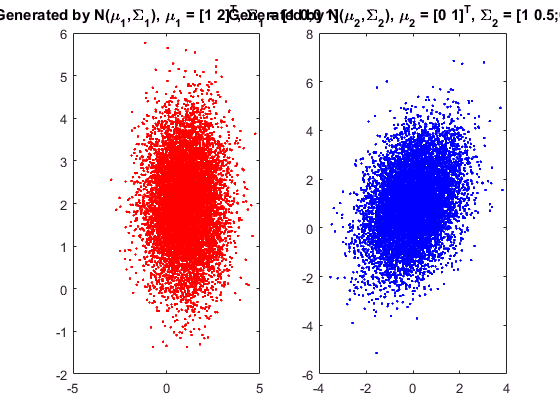

clear 
close all
clc

seed=128; % set a random seed
rng(seed);
N = 10000; % the number of points

mu1 = [1 ;2]; 
sigma1 = [1 0;0 1];  % here all the mu stands for mean and sigma stands for standard deviation
sample1 = mvnrnd(mu1,sigma1,N);
subplot(1,2,1)
plot(sample1(:,1),sample1(:,2),'r.')
title('Generated by N(\mu_1,\Sigma_1), \mu_1 = [1 2]^T, \Sigma_1 = [1 0;0 1]')
mu2 = [0 ;1];
sigma2 = [1 0.5;0.5 2];  % here all the mu stands for mean and sigma stands for standard deviation
sample2 = mvnrnd(mu2,sigma2,N);
subplot(1,2,2)
plot(sample2(:,1),sample2(:,2),'b.')
title('Generated by N(\mu_2,\Sigma_2), \mu_2 = [0 1]^T, \Sigma_2 = [1 0.5;0.5 2]')

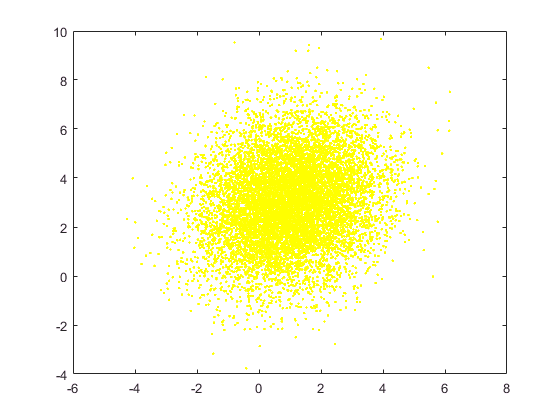


figure
sample3 = sample1+ sample2;
plot(sample3(:,1),sample3(:,2),'y.')
hold on

sample4 = mvnrnd(mu1+mu2,sigma1 + sigma2,N);

Error using  + 
Matrix dimensions must agree.


plot(sample4(:,1),sample4(:,2),'g.')
legend('Sample 1 + Sample 2','Generated by \mu = \mu_1 +\mu_2, \Sigma = \Sigma_1 + \Sigma_2')
figure
subplot(1,3,1)
plot(sample1(:,1),sample1(:,2),'r.')
title('Generated by N(\mu_1,\Sigma_1), \mu_1 = [1 2]^T, \Sigma_1 = [1 0;0 1]')
subplot(1,3,2)
histfit(sample1(:,1))
title('View of y_1')
subplot(1,3,3)
histfit(sample1(:,2))
title('View of y_2')